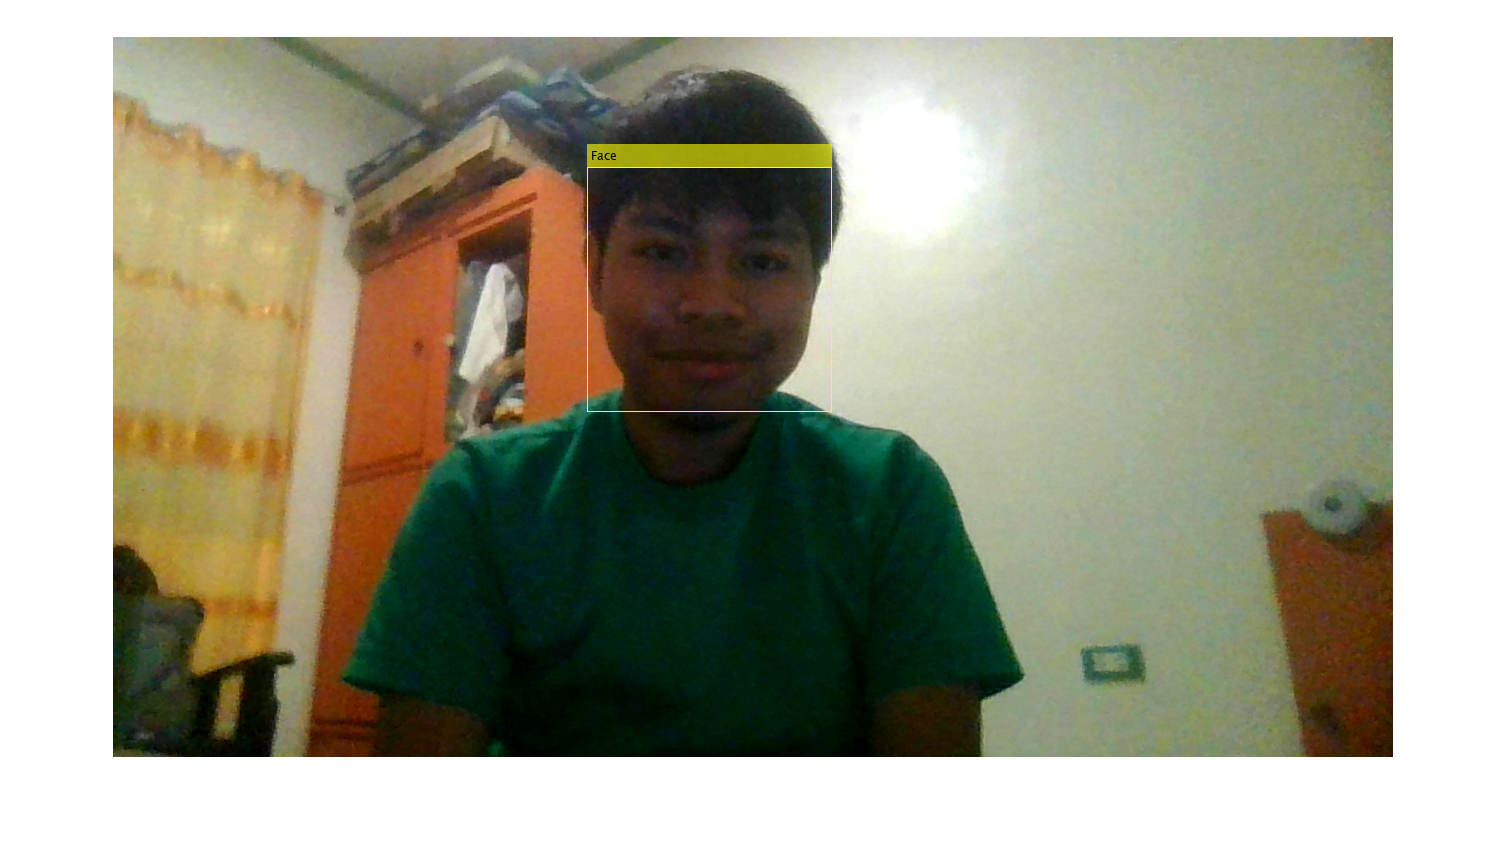

clc;
clear;
close all;

%% =========================
% 1. CONNECT TO WEBCAM
%% =========================
cam = webcam;   % default webcam

%% =========================
% 2. CREATE FACE DETECTOR
%% =========================
faceDetector = vision.CascadeObjectDetector();

%% =========================
% 3. CREATE FIGURE WINDOW
%% =========================
figure;

%% =========================
% 4. REAL-TIME DETECTION LOOP
%% =========================
while true

    % Capture frame
    img = snapshot(cam);

    % Convert to grayscale (better detection accuracy)
    grayImg = rgb2gray(img);

    % Detect faces
    bbox = step(faceDetector, grayImg);

    % Draw bounding boxes
    if ~isempty(bbox)
        img = insertObjectAnnotation(img, 'rectangle', bbox, 'Face');
    end

    % Show output
    imshow(img);
    title('Real-Time Face Detection (Press Ctrl+C to Stop)');

    drawnow;

end